% Read in the image
t = Tiff('project\images\image-example-1.tif','r');
img = read(t);
img = im2double(img);

% Get colormap from image
n = 10;
[~,cmap] = rgb2ind(img, n);
palette = cmap;

% Set the pearl size (in pixels)
pearlSize = 16

pearlSize = 16


% Rescale image to FHD
img = imresize(img,[NaN 1920]);

% Create the pearl board
board = createPearlBoard(img, pearlSize, palette)

board = board(:,:,1) =

  Columns 1 through 999

    0.5547    0.5547    0.5547    0.5547    0.5216    0.5216    0.5216    0.5216    0.5216    0.5216    0.5216    0.5547    0.5547    0.5547    0.5547    0.5547    0.5547    0.5547    0.5547    0.5547    0.5216    0.5216    0.5216    0.5216    0.5216    0.5216    0.5216    0.5547    0.5547    0.5547    0.5547    0.5547    0.5547    0.5547    0.5547    0.5547    0.5216    0.5216    0.5216    0.5216    0.5216    0.5216    0.5216    0.5547    0.5547    0.5547    0.5547    0.5547    0.5547    0.5547    0.5547    0.5547    0.5216    0.5216    0.5216    0.5216    0.5216    0.5216    0.5216    0.5547    0.5547    0.5547    0.5547    0.5547    0.5547    0.5547    0.5547    0.5547    0.5216    0.5216    0.5216    0.5216    0.5216    0.5216    0.5216    0.5547    0.5547    0.5547    0.5547    0.5547    0.5547    0.5547    0.5547    0.5547    0.5216    0.5216    0.5216    0.5216    0.5216    0.5216    0.5216    0.5547    0.5547    0.5547    0.5547 

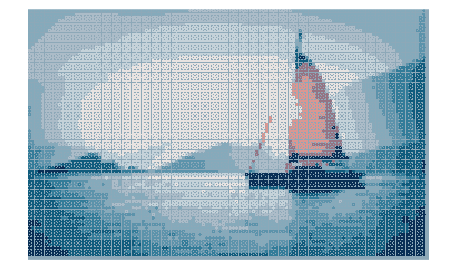


imshow(board)

function result = createPearlBoard(image, pearlSize, palette)
    % Input: An image and the size of the pearl (in width)
    % Output: A copy of the image but displayed using pearls
    [x, y, z] = size(image);

    % Convert cmap to LAB for efficiency
    palette_lab = zeros(length(palette),3);
    for i = 1:length(palette)
        palette_lab(i,:) = rgb2lab(palette(i,:));
    end

    % Scaling of the resulting image to allow for higher resolution
    board = zeros(x,y,z,'double');

    % Get the mean color from the image to use as background
    mr = mean(mean(image(:,:,1)));
    mg = mean(mean(image(:,:,2)));
    mb = mean(mean(image(:,:,3)));

    backgroundColor = [mr,mg,mb];

    board(:,:,1) = backgroundColor(1);
    board(:,:,2) = backgroundColor(2);
    board(:,:,3) = backgroundColor(3);

    % Go through the image block by block and choose a color to give a
    % pearl. Replace the part of the image with the pearl.
    for r = 1:pearlSize:x-pearlSize
        for c = 1:pearlSize:y-pearlSize
            part = image(r:r+pearlSize-1,c:c+pearlSize-1, :);
            index = getClosestPaletteColor_2(part, palette_lab);
            color = palette(index,:);

            % Create the pearl from a color
            pearlColor = makePearl(part, color, backgroundColor);

            % Place the pearl on the board
            board(r:r+pearlSize-1,c:c+pearlSize-1, :) = pearlColor;
        end
    end

    result = board;
end

function index = getClosestPaletteColor_2(part, palette)
    partColor = mean(mean(part));
    lab = rgb2lab([partColor(1), partColor(2), partColor(3)]);
    L1 = lab(1);
    a1 = lab(2);
    b1 = lab(3);
    
    best = 999;
    index = 0;

    for i = 1:length(palette)
%         lab = rgb2lab(palette(i,:));
%         L2 = lab(1);
%         a2 = lab(2);
%         b2 = lab(3);
        L2 = palette(i,1);
        a2 = palette(i,2);
        b2 = palette(i,3);
        delta = sqrt((L1-L2).^2 + (a1-a2).^2 + (b1-b2).^2);

        if delta < best
            best = delta;
            index = i;
        end
    end
end

function part = makePearl(part, color, backgroundColor)
    % Input: A part of an image which will be converted to a pearl
    % Output: An image the same size as the part but converted to a pearl
    [x, y, ~] = size(part);
    middle = x/2;
    for r = 1:x
        for c = 1:y
            d = sqrt((r-middle)^2 + (c-middle)^2);
            if d > uint8(x*0.5)
                part(r,c, :) = backgroundColor;
            elseif d <  uint8(x*0.1)
                part(r,c, :) = backgroundColor;
            else
                part(r,c, :) = color;
            end
        end
    end
end